# Péndulo no lineal (mínimos cuadrados,ODEs, interfaz de usuario)

Programación - 2023 I

Maestría en Ingeniería

Grupo No. 2: Luis Felipe Gualdron - Carlos A. Ibarra

Soluciones a la ecuacion del movimiento del péndulo simple

Lectura de los datos 

clear all, clc
data_gr = readtable('pendulo_2_gr.csv');  
data_pq = readtable('pendulo_2_pq.csv');


Ajuste de la función del péndulos simple lineal a una de armónico simple


$$\theta \left(t\right)=\theta_{m\;} \sin \left(\omega_n t+\phi \right)$$


Estimacion de parementros $\theta_{m\;} \;y\;\phi$ de acuerdo a las condiciones de fronteta para angulos pequeños

Condiciones de fontera uno (BC 1)


$$\dot{\theta} \left(0\right)=0$$


$\dot{\theta} \left(t\right)=\theta_{m\;} \omega_n \cos \left(\omega_n t+\phi \right)$  Funcion de velocidad angular (Rapidez angular)


$$0=\theta_{m\;} \omega_n \cos \left(\omega_n \left(0\right)+\phi \right)$$



$$0=\theta_{m\;} \omega_n \cos \left(\phi \right)$$



$$0=\cos \left(\phi \right)$$



$$\cos^{-1} \left(0\right)=\phi$$


$\frac{\pi }{2}=\phi$ (1)

Condiciones de fontera dos (BC 2)


$$\theta \left(0\right)=\theta_0$$



$$\theta \left(t\right)=\theta_{m\;} \sin \left(\omega_n t+\phi \right)$$
  


$$\theta_0 =\theta_{m\;} \sin \left(\phi \right)$$
  

$\frac{\theta_0 }{\sin \left(\phi \right)}=\theta_{m\;}$ (2)

Se asumiría como condición inicial  como promedio de la diferencia entre el maximo y minimo del registro del angulo $\theta$ 


$$\theta_0 =\frac{\theta_{\max } -\theta_{\min } }{2}$$


Lectura y conversion de unidades de los datos experimentales 

Datos de tiempo [s]

Data_t = data_pq(4:61,"Var1"); 

Datos de tiempo extraidos de la base de datos 

Data_tiempo = table2array(Data_t);  

Datos de angunlo Pequeño  [grados]

Data_pq_deg = data_pq(4:61,"Var2"); 

Datos de angunlo Pequeño [radianes]

Data_pq_rad = deg2rad(table2array(Data_pq_deg));

Datos de angunlo grande  [grados]

Data_gr_deg = data_gr(4:61,"Var2");

Datos de angunlo grande [radianes]

Data_gr_rad = deg2rad(table2array(Data_gr_deg));

Datos de rapidez para angulo pequeño [grado/s]

Data_Rapidez_pq = data_pq(4:61,"Var3");

Datos de rapidez para angulo pequeño [grado/s]

Data_Rapidez_gr = data_gr(4:61,"Var3");

Datos de rapidez para angulo pequeño [rad/s]

Data_Rapidez_pq_rad = deg2rad(table2array(Data_Rapidez_pq));

Datos de rapidez para angulo grande [rad/s]

Data_Rapidez_gr_rad = deg2rad(table2array(Data_Rapidez_gr));

Calculo del angulo inicial, amplitud $\theta_{m\;}$y corrimiento de los datos

### ** Resultados para los datos de angulo pequeño **

disp('Resultados para los datos de angulo pequeño')

Resultados para los datos de angulo pequeño


Theta0_pq = (max(Data_pq_rad)-min(Data_pq_rad))/2

Theta0_pq = 0.1833

Phi    = pi/2

Phi = 1.5708

Thetam_pq = Theta0_pq/sin(Phi)

Thetam_pq = 0.1833

Grafico de posicion  angular de datos experimentales con angulos pequeños

figure (1) 
t = Data_tiempo;
y = Data_pq_rad + Theta0_pq;
plot(t,y,'ro')

Estimacion del maramentro de frencuencia angular utilizando la función `lsqcurvefit`

La función `lsqcurvefit` resuelve este tipo de problema fácilmente.

Parámetro en término de una variable x para la estimación

F = @(x,xdata)(Thetam_pq)*sin(x(1)*xdata + Phi);

Estimacion a partir de un valor semilla 

x00 = [5];
[x,resnorm,~,exitflag,output] = lsqcurvefit(F,x00,t,y);


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


disp('Frecuencia natural circular del sistema')

Frecuencia natural circular del sistema


w_n_pq = x

w_n_pq = 5.5134

Grafico de la funcion de posicion angular

figure (1)
hold on 
grid on
ODE = sim("Pendulo_No_Lineal.slx")

ODE =   Simulink.SimulationOutput:

              ScopeData: [61x2 double] 
             ScopeData1: [61x2 double] 
                   tout: [61x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


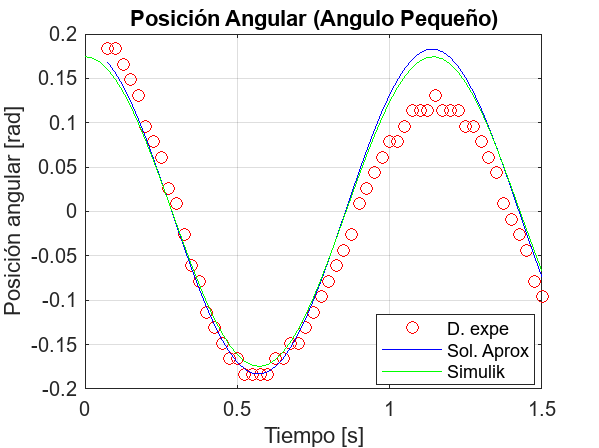

Tiempo = ODE.ScopeData(:,1);
Posicion = ODE.ScopeData(:,2);
plot(t,F(x,t),'b',Tiempo,Posicion,'g')
title ('Posición Angular (Angulo Pequeño)')
legend('D. expe','Sol. Aprox','Simulik');
legend("Position", [0.63662,0.1668,0.24814,0.10675]);
xlabel('Tiempo [s]');
ylabel('Posición angular [rad]');

Grafico de la repidez angular para la solucion apoximada 

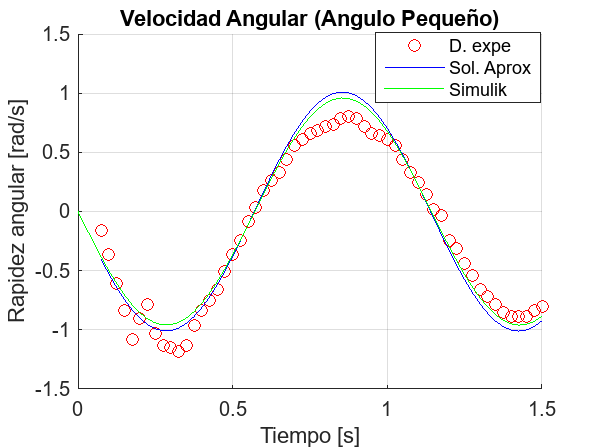

figure ()
hold on
grid on
Tiempo = ODE.ScopeData(:,1);
RapidezODE = ODE.ScopeData1(:,2);
Rapidez = (Thetam_pq)*x*cos(x(1)*t + Phi);
plot(t,Data_Rapidez_pq_rad,'ro',t,Rapidez,'b',Tiempo,RapidezODE,'g')
title ('Velocidad Angular (Angulo Pequeño)')
legend('D. expe','Sol. Aprox','Simulik');
legend("Position", [0.62845,0.79193,0.27296,0.11595]);
xlabel('Tiempo [s]');
ylabel('Rapidez angular [rad/s]');

Calculo del error para los datos de posicion angular 

Area_DataExpe_P   = abs(trapz(t,y));
Area_DataSolAp_P  = abs(trapz(t,F(x,t)));
Area_DataODE_P    = abs(trapz(Tiempo,Posicion));


disp('Error relativo para los resultados de posicion')

Error relativo para los resultados de posicion


ErrorSolAp_P      = abs(((Area_DataSolAp_P - Area_DataExpe_P)/Area_DataSolAp_P)*100)

ErrorSolAp_P = 37.1848

ErrorODE_P        = abs(((Area_DataODE_P - Area_DataExpe_P)/Area_DataODE_P)*100)

ErrorODE_P = 63.4518

Calculo del error para los datos de velocidad angular 

Area_DataExpe_V   = abs(trapz(t,Data_Rapidez_pq_rad));
Area_DataSolAp_V  = abs(trapz(t,Rapidez));
Area_DataODE_V    = abs(trapz(Tiempo,RapidezODE));

disp('Error relativo para los resultados de velocidad')

Error relativo para los resultados de velocidad


ErrorSolAp_V      = abs(((Area_DataSolAp_V - Area_DataExpe_V)/Area_DataSolAp_V)*100)

ErrorSolAp_V = 16.7990

ErrorODE_V        = abs(((Area_DataODE_V- Area_DataExpe_V)/Area_DataODE_V)*100)

ErrorODE_V = 16.8638

** Resultados para los datos de angulo grande **

disp('Resultados para los datos de angulo grande')

Resultados para los datos de angulo grande


Theta0_gr = (max(Data_gr_rad)-min(Data_gr_rad))/2

Theta0_gr = 0.8029

Phi    = pi/2

Phi = 1.5708

Thetam_gr = Theta0_gr/sin(Phi)

Thetam_gr = 0.8029

Grafico de posicion  angular de datos experimentales con angulos grandes 

t = Data_tiempo;
y_gr = Data_gr_rad + Theta0_gr;

Estimacion del maramentro de frencuencia angular utilizando la función `lsqcurvefit`

La función `lsqcurvefit` resuelve este tipo de problema fácilmente.

Parámetro en término de una variable x para la estimación

Ff = @(xx,xdata)(Thetam_gr)*sin(xx(1)*xdata + Phi);

Estimacion a partir de un valor semilla 

x00 = [5];
[xx,resnorm,~,exitflag,output] = lsqcurvefit(F,x00,t,y_gr);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


disp('Frecuencia natural circular del sistema')

Frecuencia natural circular del sistema


w_n_gr = xx

w_n_gr = 4.6211

Grafico de la funcion de posicion angular

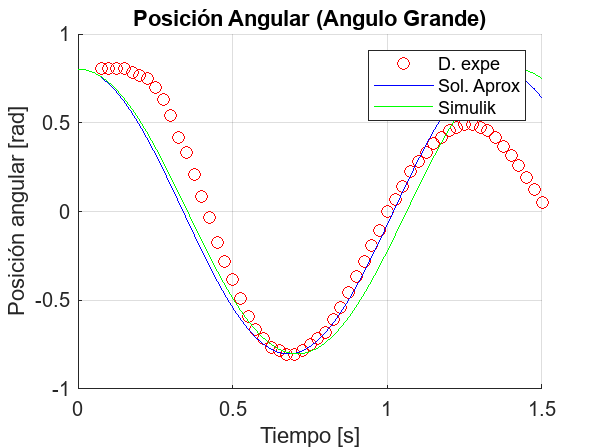

ODE = sim("Pendulo_No_Lineal_gr.slx");
Tiempo = ODE.ScopeData(:,1);
Posicion = ODE.ScopeData(:,2);
figure ()
hold on 
grid on 
Posicion_gr = (Thetam_gr)*sin(w_n_gr*t + Phi);
plot(t,y_gr,'ro',t,Posicion_gr,'b',Tiempo,Posicion,'g')
title ('Posición Angular (Angulo Grande)')
legend('D. expe','Sol. Aprox','Simulik');
xlabel('Tiempo [s]');
ylabel('Posición angular [rad]');

Calculo del error para los datos de posicion angular

Area_DataExpe_P   = abs(trapz(t,y_gr));
Area_DataSolAp_P  = abs(trapz(Posicion_gr));
Area_DataODE_P    = abs(trapz(Posicion));


disp('Error relativo para los resultados de posicion')

Error relativo para los resultados de posicion


ErrorSolAp_P      = abs(((Area_DataSolAp_P - Area_DataExpe_P)/Area_DataSolAp_P)*100)

ErrorSolAp_P = 96.6818

ErrorODE_P        = abs(((Area_DataODE_P - Area_DataExpe_P)/Area_DataODE_P)*100)

ErrorODE_P = 97.6750

Grafico de la rapidez angular para la solucion apoximada 

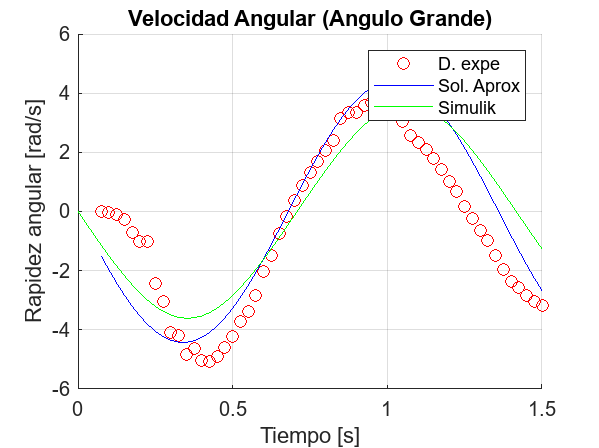

figure ()
hold on
grid on
ODE = sim("Pendulo_No_Lineal_gr.slx");
Tiempo = ODE.ScopeData(:,1);
RapidezODE_gr = ODE.ScopeData1(:,2);
Rapidez_gr = (Thetam_gr)*x*cos(w_n_gr*t + Phi);
plot(t,Data_Rapidez_gr_rad,'ro',t,Rapidez_gr,'b',Tiempo,RapidezODE_gr,'g')
title ('Velocidad Angular (Angulo Grande)')
legend('D. expe','Sol. Aprox','Simulik');
xlabel('Tiempo [s]');
ylabel('Rapidez angular [rad/s]');

Calculo del error para los datos de velocidad angular 

Area_DataExpe_V   = abs(trapz(t,Data_Rapidez_gr_rad));
Area_DataSolAp_V  = abs(trapz(Rapidez_gr));
Area_DataODE_V    = abs(trapz(RapidezODE_gr));

disp('Error relativo para los resultados de velocidad')

Error relativo para los resultados de velocidad


ErrorSolAp_V      = abs(((Area_DataSolAp_V - Area_DataExpe_V)/Area_DataSolAp_V)*100)

ErrorSolAp_V = 85.9386

ErrorODE_V        = abs(((Area_DataODE_V- Area_DataExpe_V)/Area_DataODE_V)*100)

ErrorODE_V = 63.2870